% It optimises the cost function of SUM (xr-x)^2 + u^2

xref = xr_array;    % array of reference trajectory
Tsamp = Ts;         % Sampling time
T = 1;              % Current real time
currPos = 0; 
currVel = 0; 
k_effort = 0.001;   % coefficient on u^2 term in cost func 
k_track = 1;        % coefficient on (xr-x)^2 term in cost func 
horizon = 1;        % How many seconds you look in the future. 

% number of data points
N = double(int32(horizon/Tsamp));

N = 200;

% reference x = step funciton 
currT = int32(T/Tsamp)+1;
xref = xref(currT:currT+N);

% initial condition
x0 = [currPos currVel];

A = [1 Tsamp; 0 1];
B = [0; Tsamp];

mat = zeros(2, N);

for i = 1:N
    mat(:,i) = (A^(i-1))*B;
end

H = 2*eye(2*N-1); % x2 to counteract the 1/2 coefficient in the solver

for i = 1:2*N-1 
    if i <= N
        H(i,i) = k_track*H(i,i);    
    else
        H(i,i) = k_effort*H(i,i);
    end
end

f = zeros(2*N-1,1);

for i = 1:N
    f(i) = -2*k_track*xref(i);
end

Aineq = [];
bineq = [];
Aeq = zeros(2*N-1);
beq = zeros(2*N-1, 1);
lb = zeros(2*N-1,1);
ub = zeros(2*N-1,1);

% set values in Aeq
Aeq(1,1) = 1;

for i = 2:N
    Aeq(i,i) = -1;
end

for i = 2:N
    Aeq(i, 1) = [1,0]*A^(i-1)*[1;0]; 
    
    p = zeros(1, N-1);
    p(1:i-1) = flip(mat(1, 1:i-1));
    Aeq(i,N+1:end) = p;
end

beq(1) = x0(1);
for i = 2:N
    beq(i) = -1*[1,0]*A^(i-1)*[0;1]*x0(2);
end

u_lim = Tsamp*1000;
for i = 1:2*N-1
    if i <= N
        lb(i) = -inf;
        ub(i) = inf;
    else
        lb(i) = -1*u_lim;
        ub(i) = u_lim;
    end
end


%x0 = zeros(2*N-1,1);
%options = optimoptions('quadprog','Algorithm','active-set');

z = quadprog(H,f,Aineq,bineq,Aeq,beq,lb,ub); %,x0,options);


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


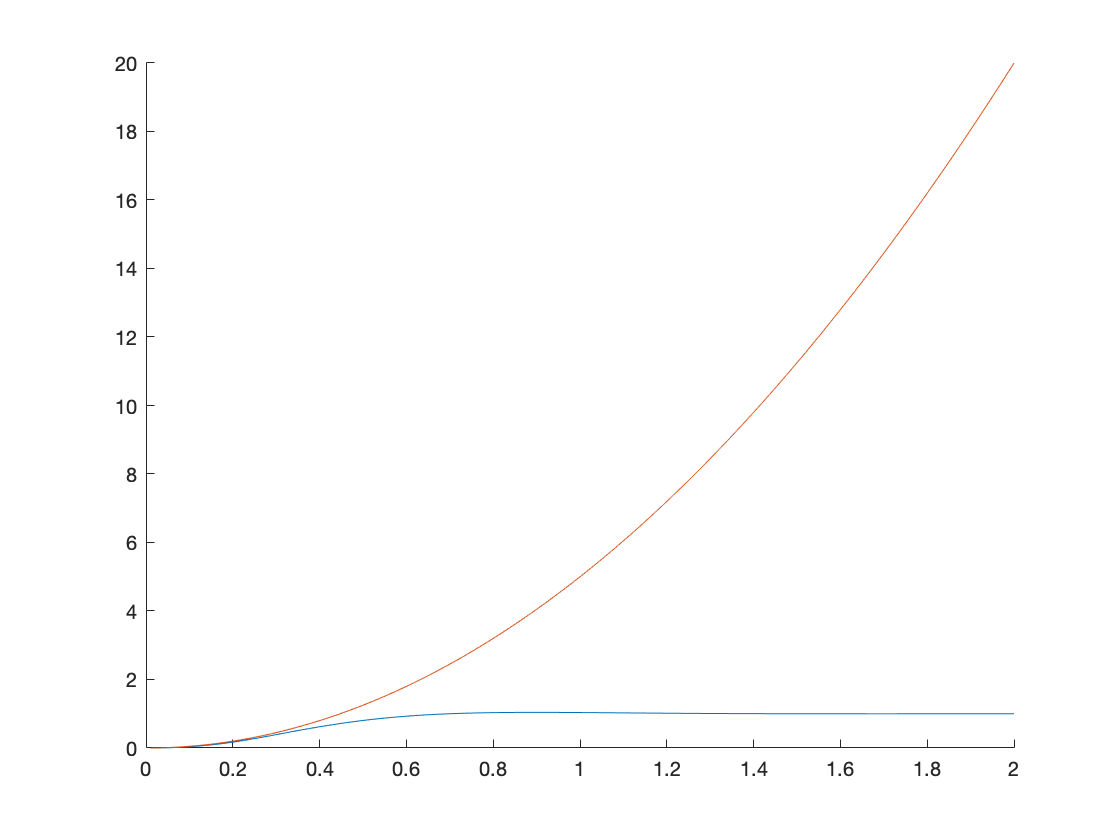


% plotting now
x_test = ones(N, 1);
t = ones(N, 1);
tu = ones(N-1, 1);
for i = 1:N
    t(i) = i*Ts;
    if i < N
        tu(i) = i*Ts;
    end
    
    x_test(i) = 5*(i*Ts)^2;
end

u = z(N+1:end);
x = z(1:N);

figure;
hold on;
plot(t, x);
plot(t, x_test);

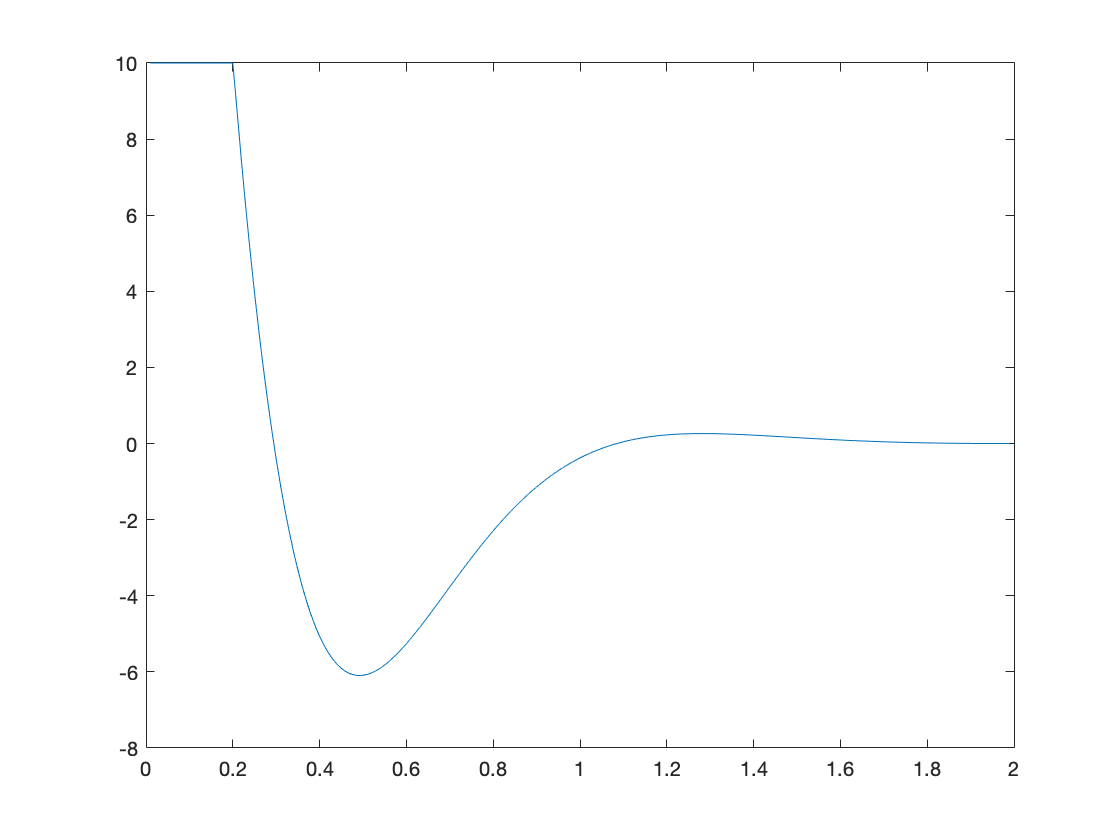

%plot(t, xref);

figure;
plot(t(1:end-1), u);


u_timeseries = timeseries(u, tu);

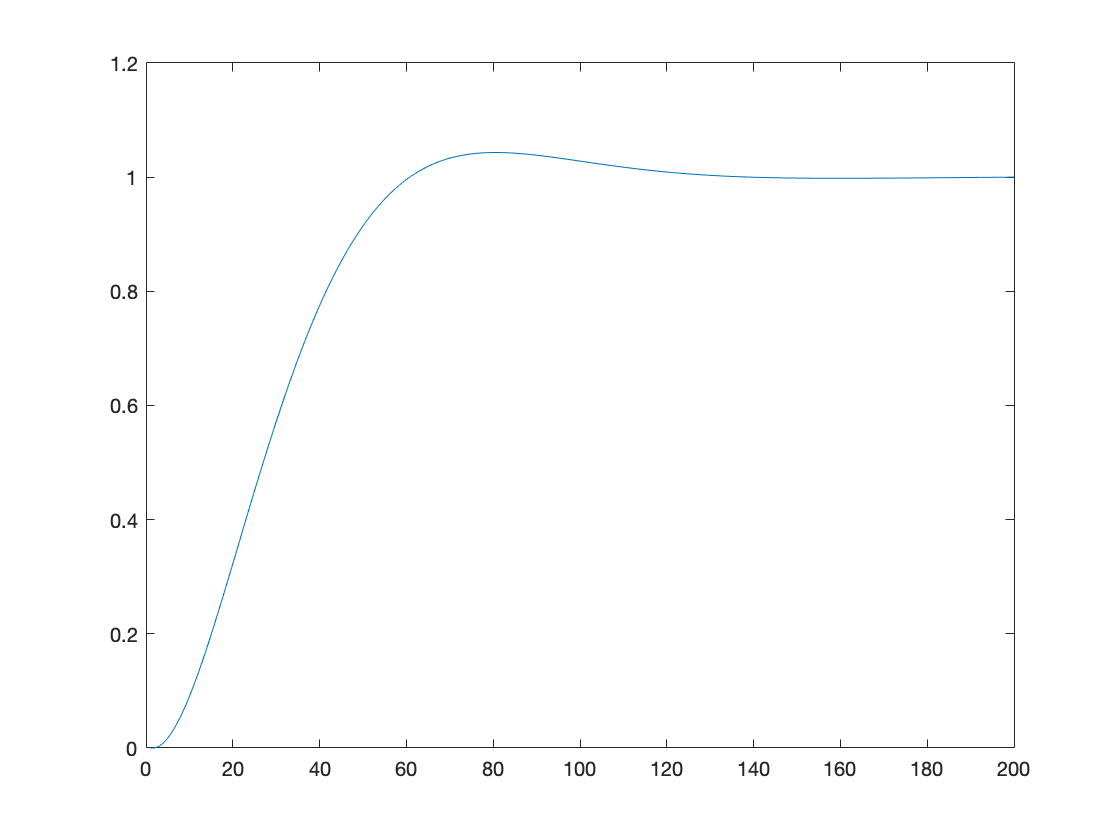

%Sanity check
x1 = x0';

x_sanity = zeros(N, 0);

x_sanity(1) = x1(1);
x_prev = x1;
for i = 2:N
    x_curr = A*x_prev + B*u(i-1);
    
    %disp(i)
    %x_curr
    x_sanity(i) = x_curr(1);
    x_prev = x_curr;
end

plot(x_sanity)